# Tunnel Characterization - Pitot Probe 3/18/2025

% Take ascending pressure points starting at ~0.3 kPa and plot

pitot_cal_P5 = [0.30 10.1 19.75 29.27 39.19]; % Para Scientific readout (kPa)

pitot_cal_V5 = [-3.669 -1.819 -0.005 1.787 3.650]; % Voltage readout (KSC-2 balanced at -30.4199 mV)


## Quick Fit Check

x = pitot_cal_V5;
y = pitot_cal_P5;

X = linspace(-4,6,1e3); % for this, linspace(lowest x-axis value, highest, # of desired points)

% Calculate polynomial coefficients
p1 = polyfit(x, y, 1);

% Evaluate polynomials
y_fit1 = polyval(p1, X);

y_cfit1 = polyval(p1, x);

% error

sig_y1 = sqrt((sum((y - y_cfit1).^2)/(length(x)-2)));

err1 = t_value(0.9, length(x)-2)*sig_y1

% Plot the original data and the fitted polynomials
figure;
plot(x, y, 'ro', 'DisplayName', 'Original Data');
hold on;
grid on
plot(X, y_fit1, 'k-', 'DisplayName', 'Degree 1 Polynomial');
hold off;

% Add labels and legend
xlabel('Voltage Read outs (V)');
ylabel('Parascientific Readout (kPa)');
title('1st Degree Fit Calibration Curve');
legend('show','Location','northwest');


% Use best fit techniques to create calibration curve from collected data

% PitotCal_1 = table2array(KCal5_4);
% PitotCal_2 = table2array(KCal5_5);
% PitotCal_3 = table2array(KCal5_1); % These are all ordered weirdly because of the order I took the points, 
% PitotCal_4 = table2array(KCal5_2); % just make sure they are in ascending order by the end
% PitotCal_5 = table2array(KCal5_3);

% 
% Pitot_1 = table2array(Pitot5_1);
% Pitot_2 = table2array(Pitot5_2);
% Pitot_3 = table2array(Pitot5_3);
% Pitot_4 = table2array(Pitot5_4);
% Pitot_5 = table2array(Pitot5_5);
% Pitot_6 = table2array(Pitot5_6);


% Take drvier tube calibration from Campaign 1 or 3 analysis IF APPLICABLE

% DCal1 = table2array(DCal1);
% DCal2 = table2array(DCal2);
% DCal3 = table2array(DCal3);
% DCal4 = table2array(DCal4);
% DCal5 = table2array(DCal5);
% 
% DT_1 = table2array(DT5_Pitot1); 
% DT_2 = table2array(DT5_Pitot2);
% DT_3 = table2array(DT5_Pitot3);
% DT_4 = table2array(DT5_Pitot4);
% DT_5 = table2array(DT5_Pitot5);
% DT_6 = table2array(DT5_Pitot6);


## Driver Tube Calibration

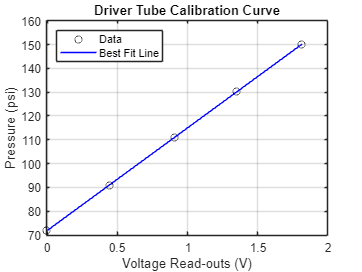

% This section plots Driver tube and Kulite calibration curves as well as
% calculates the calibration coefficients needed in later sections

% DCal data
DCal_points = [sum(DCal1)./(height(DCal1)), sum(DCal2)./(height(DCal2)), sum(DCal3)./(height(DCal3)), sum(DCal4)./(height(DCal4)), sum(DCal5)./(height(DCal5))];
DCal_pressures = [71.9 91.0 110.8 130.1 150.2];

% Calibration Curve
DCal_fit_coeffs = polyfit(DCal_pressures, DCal_points, 1);
DCal_fit = polyval(DCal_fit_coeffs, DCal_pressures);

% Plot DCal data and best-fit line
figure;
plot(DCal_points, DCal_pressures, 'ko', 'DisplayName', 'Data');
hold on
plot(DCal_fit, DCal_pressures, 'b-', 'DisplayName', 'Best Fit Line');
grid on
legend('Location', 'northwest')
ylabel('Pressure (psi)');
xlabel('Voltage Read-outs (V)');
title('Driver Tube Calibration Curve');
hold off

## Pitot Probe Calibration

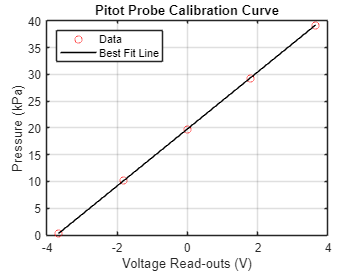

% Create mean vectors

PitotCal = [mean(PitotCal_1) mean(PitotCal_2) mean(PitotCal_3) mean(PitotCal_4) mean(PitotCal_5)];

% Find best-fit line for KCal data
PitotCal_fit_coeffs = polyfit(pitot_cal_P5, PitotCal, 1);
PitotCal_fit = polyval(PitotCal_fit_coeffs, pitot_cal_P5);

% Plot KCal data and best-fit line
figure;
plot(pitot_cal_V5, pitot_cal_P5,'ro', 'DisplayName', 'Data');
hold on
plot(PitotCal_fit, pitot_cal_P5, 'k-', 'DisplayName', 'Best Fit Line');
grid on
legend('Location', 'northwest')
ylabel('Pressure (kPa)');
xlabel('Voltage Read-outs (V)');
title('Pitot Probe Calibration Curve');
hold off

% Convert voltage traces to pressure traces (kPa)

Press_Pitot1 = (Pitot_1 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot2 = (Pitot_2 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot3 = (Pitot_3 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot4 = (Pitot_4 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot5 = (Pitot_5 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);
Press_Pitot6 = (Pitot_6 - PitotCal_fit_coeffs(2)) / PitotCal_fit_coeffs(1);

Press_DT1 = (DT_1 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT2 = (DT_2 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT3 = (DT_3 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT4 = (DT_4 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT5 = (DT_5 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);
Press_DT6 = (DT_6 - DCal_fit_coeffs(2)) / DCal_fit_coeffs(1);

time = linspace(-200,2000,550001); % time vector starting 200 ms before trigger


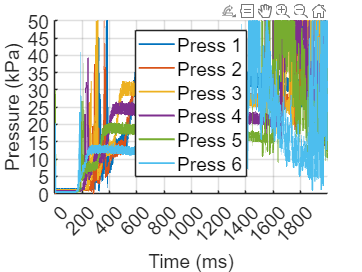

% Plot Pressure Trace
figure;
hold on

plot(time, Press_Pitot1, 'DisplayName', 'Press 1');
plot(time, Press_Pitot2, 'DisplayName', 'Press 2');
plot(time, Press_Pitot3, 'DisplayName', 'Press 3');
plot(time, Press_Pitot4, 'DisplayName', 'Press 4');
plot(time, Press_Pitot5, 'DisplayName', 'Press 5');
plot(time, Press_Pitot6, 'DisplayName', 'Press 6');

grid on

% Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% time_xlabel + 0.2 + 0.0001

fsize = 16;
xlim([time(250000 * (0 + 0.2)) time(250000 * (2.0 + 0.2))]); ...
    % time(250000 * time elapsed(sec)), dont forget 200 ms trigger
ylim([0 50]); % kPa
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(0:5:200))
ax=gca;
ax.XAxis.FontSize = fsize;
ax.YAxis.FontSize = fsize;
h = findobj(gca,'Type','line');
set(h,'LineWidth',1.5);
%title('Campaign #1 Pressure Traces',FontSize=fsize);
xlabel('Time (ms)',FontSize=fsize);
ylabel('Pressure (kPa)',FontSize=fsize);
legend('Location', 'north','Fontsize', fsize);
grid on

hold off;

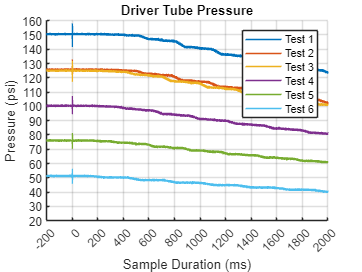

% Plot Driver Tube Pressure

figure;
hold on

plot(time, Press_DT1, 'DisplayName', 'Test 1');
plot(time, Press_DT2, 'DisplayName', 'Test 2');
plot(time, Press_DT3, 'DisplayName', 'Test 3');
plot(time, Press_DT4, 'DisplayName', 'Test 4');
plot(time, Press_DT5, 'DisplayName', 'Test 5');
plot(time, Press_DT6, 'DisplayName', 'Test 6');

% Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% Adding labels and legend
xlim([time(1) time(end)]);
%ylim([30 150])
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(20:10:160))
title('Driver Tube Pressure');
xlabel('Sample Duration (ms)');
ylabel('Pressure (psi)');
grid on
legend('show');

hold off;

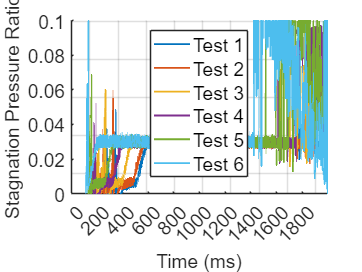

% Create stagnation pressure ratio arrays

Po2_Po1_Run1 = Press_Pitot1 ./ (6.89476 * Press_DT1);
Po2_Po1_Run2 = Press_Pitot2 ./ (6.89476 * Press_DT2);
Po2_Po1_Run3 = Press_Pitot3 ./ (6.89476 * Press_DT3);
Po2_Po1_Run4 = Press_Pitot4 ./ (6.89476 * Press_DT4);
Po2_Po1_Run5 = Press_Pitot5 ./ (6.89476 * Press_DT5);
Po2_Po1_Run6 = Press_Pitot6 ./ (6.89476 * Press_DT6);

% Plot stagantion pressure ratio traces

 figure;
 hold on 

 plot(time, Po2_Po1_Run1, 'DisplayName', 'Test 1');
 plot(time, Po2_Po1_Run2, 'DisplayName', 'Test 2');
 plot(time, Po2_Po1_Run3, 'DisplayName', 'Test 3');
 plot(time, Po2_Po1_Run4, 'DisplayName', 'Test 4');
 plot(time, Po2_Po1_Run5, 'DisplayName', 'Test 5');
 plot(time, Po2_Po1_Run6, 'DisplayName', 'Test 6');

 % Adding labels and legend

time_xlabel = 1.79; % Time in seconds displayed on x-axis of plot up to 1.79 sec

% time_xlabel + 0.2 + 0.0001

fsize = 16;
xlim([time(250000 * (0 + 0.2)) time(250000 * (2.0 + 0.2))]); ...
    % time(250000 * time elapsed(sec)), dont forget 200 ms trigger
ylim([0 0.1]); % kPa
set(gca,'XTick',(-200:200:2000))
set(gca,'YTick',(0:0.02:0.1))
ax=gca;
ax.XAxis.FontSize = fsize;
ax.YAxis.FontSize = fsize;
h = findobj(gca,'Type','line');
set(h,'LineWidth',1.5);
%title('Campaign #1 Pressure Traces',FontSize=fsize);
xlabel('Time (ms)',FontSize=fsize);
ylabel('Stagnation Pressure Ratio',FontSize=fsize);
legend('Location', 'north','Fontsize', fsize);
grid on

hold off;

## Average Mach number during steady-state run time

Tstart = 0.45; % time elapsed where steady state begins (sec)
Tend = 1.3; % time elapsed where steady state ends (sec)

% Find Mean of steady-state run time stagnation pressure, Po2 just passed Normal Shock

Po2 = mean(Press_Pitot6([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])) % (kPa)

Po2 = 11.8139


% Find Mean of corresponding Driver Tube pressure, Po1, convert to kPa

Po1 = 6.89476 * mean(Press_DT6([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])) % (kPa)

Po1 = 322.9146


% Find Po2 / Po1

Avg_Po2_Po1 = Po2 / Po1

Avg_Po2_Po1 = 0.0366


% Solve for Upstream Mach Number using Po2/Po1 via Normal Shock Relations
% Note: simplified for gamma = 1.4

NormalShockRelation = @(M) ((2.4 * M^2) / (0.4 * M^2 + 2))^3.5 * ...
    (2.4 / (2.8 * M^2 - 0.4))^2.5 - Avg_Po2_Po1;

Avg_Minf = fzero(NormalShockRelation, [1,7]) % [1,7] being the range of guesses

Avg_Minf = 5.7022

## Error in Stagnation Pressures

Po1_error = sqrt((1000 * 6.89476 * (0.1 / 100))^2 +...
    (std(Press_DT6([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])))^2) % Driver tube uncertainty for 1000A in kPa

Po1_error = 7.0568


%Po2_error_50A = sqrt((50 * 6.89476 * (0.1 / 100))^2 + ...
    %(std(Press_KrunXX([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])))^2) % Kulite uncertainty for 50A in kPa

Po2_error_10A = sqrt((10 * 6.89476 * (0.1 / 100))^2 + ...
     (std(Press_Pitot6([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])))^2)% Kulite uncertainty for 10A in kPa

Po2_error_10A = 0.4888



%error_po2_po1_50A= sqrt((Po2_error_50A * (1 / Po1))^2) + (Po1_error * (-Po2 / (Po1)^2)^2) % Uncertainty of po2/po1
% percent_err_po2_po1_50A = error_po2_po1_50A / Avg_Po2_Po1

error_po2_po1_10A= sqrt((Po2_error_10A * (1 / Po1))^2) + (Po1_error * (-Po2 / (Po1)^2)^2) % Uncertainty of po2/po1

error_po2_po1_10A = 0.0015

percent_err_po2_po1_10A = (error_po2_po1_10A / Avg_Po2_Po1) * 100

percent_err_po2_po1_10A = 4.1377

## Error in Mach Number

syms M
% Define the expression
expr = ((2.4 * M^2) / (0.4 * M^2 + 2))^3.5 * (2.4 / (2.8 * M^2 - 0.4))^2.5;

% Compute the derivative with respect to M
diff_expr = diff(expr, M);

% Display the derivative
disp('Derivative:');

Derivative:


disp(diff_expr);

$$\begin{array}{l} \frac{7\,{\left(\frac{12}{5\,\sigma_{1}}\right)}^{5/2}\,\left(\frac{24\,M}{\sigma_{3}}-\frac{48\,M^{3}}{25\,{\left(\frac{2\,M^{2}}{5}+2\right)}^{2}}\right)\,{\sigma_{2}}^{5/2}}{2}-\frac{168\,M\,{\left(\frac{12}{5\,\sigma_{1}}\right)}^{3/2}\,{\sigma_{2}}^{7/2}}{5\,{\sigma_{1}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\frac{14\,M^{2}}{5}-\frac{2}{5}\\ \sigma_{2}=\frac{12\,M^{2}}{\sigma_{3}}\\ \sigma_{3}=5\,\left(\frac{2\,M^{2}}{5}+2\right) \end{array}$$


% Evaluate the derivative at a specific value of M
M_value = Avg_Minf; % input M
evaluated_diff = 1 / double(subs(diff_expr, M, M_value));

% Display the evaluated result
disp(['The derivative at M = ', num2str(M_value), ' is: ', num2str(evaluated_diff)]);

The derivative at M = 5.7022 is: -38.1163




% Convert the symbolic expression to a function handle
f = matlabFunction(expr);

% Define the range for M
M_values = linspace(1, 7, 100); % 100 points from M = 1 to M = 7

% Evaluate the expression for each value of M
y_values = f(M_values);

% Plot the result
% figure;
% plot(y_values, M_values, 'LineWidth', 2);
% ylabel('M');
% xlabel('Po2 / Po1');
% title('Plot from M = 1 to M = 7');
% grid on;


% error_mach_50A = sqrt((error_po2_po1_50A * evaluated_diff)^2)
error_mach_10A = sqrt((error_po2_po1_10A * evaluated_diff)^2)

error_mach_10A = 0.0577

## Determine Tunnel noise via pressure trace deviation from mean

% NOTE: For Tstart, use the "humps" in driver tube traces to find clean SS times 
% NOTE: This doesn't take into account the cavity resonance of the kulite, but is a common comparison point to other tunnels

% Tstart = 0.3; % time elapsed where steady state driver tube "hump" occurs (sec)
Tend = Tstart + 0.15; % 0.05 seconds after Tstart for clean data pull (sec)

Run = Press_Pitot6;

Pressmean = mean(Run([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])); % (kPa)

deviation = std(Run([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])); % (kPa)

Meanremoved = Run - Pressmean;

rootms_withmean = rms(Run([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))]), 1); % (kPa)

rootms_removed = rms(Meanremoved([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))]), 1); % (kPa)

noise_mean = 100 * (rootms_removed / Pressmean) % Percent noise level

noise_mean = 2.7131


% NOTE: This doesn't take into account the cavity resonance of the kulite

% RMS and Mean Noise levels
               
                  % DT (psi)    Vac (kPa)   

% noise1 = %                           
% noise2 = %              
% noise3 = %              
% noise4 = %              
% noise5 = %              
% noise6 = %              
% noise7 = %              


## PSD Calc

figure

hold on
fsamp = 250*10^3;
pointsperblock = 1000;
smoothened = 0;

% Tstart = 0.55; % time elapsed where steady state driver tube "hump" occurs (sec)
% Tend = Tstart + 0.05; % 0.05 seconds after Tstart for clean data pull (sec)

% Run = Press_KRun46;

Pressmean = mean(Run([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])); % (kPa)
noMean = Run([(250000 * (Tstart + 0.2)) : (250000 * (Tend + 0.2))])-Pressmean;

[Sxx_mean,LLL] = PSD(noMean,fsamp,pointsperblock,smoothened);
StanDev = sqrt(trapz(LLL(1:200),Sxx_mean(1:200)));

(StanDev/Pressmean)*100

ans = 1.9085

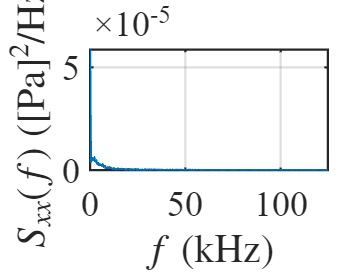


hold off


% PSD Noise levels
               
                  % DT (psi)    Vac (kPa)   

% noise1 =             
% noise2 = 
% noise3 = 
% noise4 = 
% noise5 = 
% noise6 = 
% noise7 = 

% Po2_mean_array = []; % kPa